# Dynamics Simulation 

Dynamic Simulation for the 6 DoF Space Robot

clc
% load 'SR6.mat'

sr.homeConfig();
q_0 = sr.q;
q_dot_0 = sr.q_dot;

Parameters

fileName = '';          % Where to save animation, Do not save if left as ''
animationTEnd = 10;     % When to stop animation time

simTime = '10.0';       % Simulation end time

% Forces
fx = 10;
fy = 0;
fz = 0;

nx = 0;
ny = 0;
nz = 0;

tau1 = 0;
tau2 = 0;
tau3 = 0;
tau4 = 0;
tau5 = 0;
tau6 = 0;

tau = [tau1; tau2; tau3; tau4; tau5; tau6];

f = -0.2;
dt = 1;

### Launch Simulation

% profile on
tic
set_param('open_loop_dyn', 'StopTime', simTime)
simRes = sim('open_loop_dyn');

MATLAB System block 'open_loop_dyn/Subsystem Reference1/Forward Dynamics/MATLAB System' error occurred when invoking 'stepImpl' method of
'ForwardDynBlock'. The error was thrown from '
 'C:\Users\charl\Documents\Git\space-manipulator\Project\Models\SR6\SR6_info.m' at line 4
 'C:\Users\charl\Documents\Git\space-manipulator\Project\Models\SR6\SR6_state_func.m' at line 2
 'C:\Users\charl\Documents\Git\space-manipulator\My Toolbox\Simulink_lib\src\ForwardDynBlock.m' at line 37
 

toc
% profile viewer
% profile off

### Animate Results

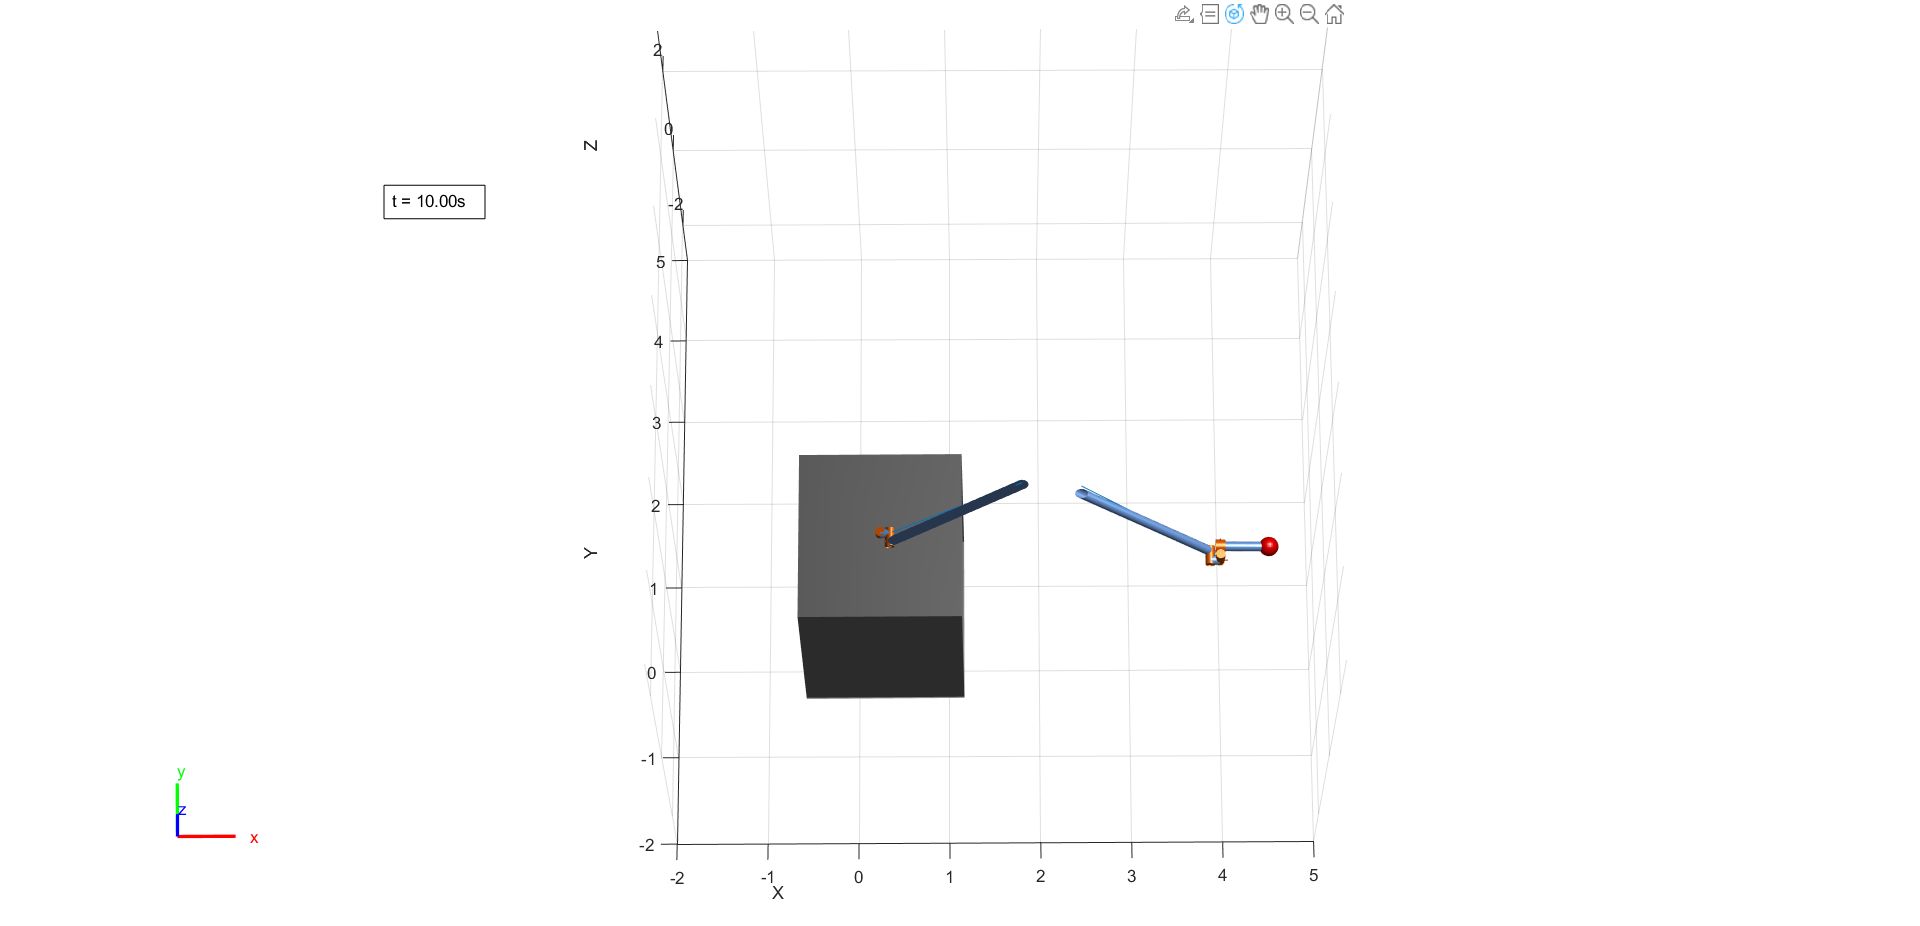

clc
close all
folder = 'Project/Videos/';

data = simRes.q.getsampleusingtime(0, animationTEnd);

if ~strcmp(fileName, '')
    savePath = strcat(folder, fileName);
else
    savePath = '';
end

tic
sr.animate(data, 'fps', 17, 'rate', 1, 'fileName', savePath); 

toc

Elapsed time is 14.291139 seconds.
